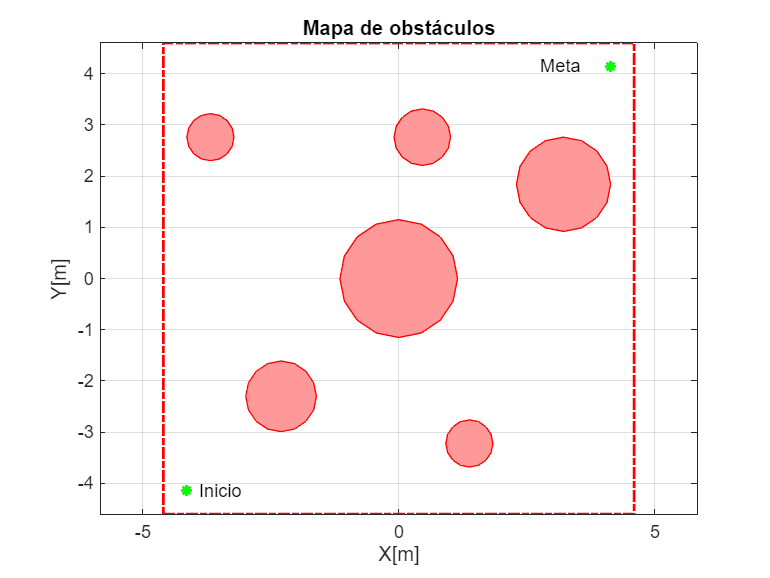

clear
% 1. Crear mapa con obstáculos
R = 0.92 / 2;
k = 10 * R;
CC = k * 0.1 * [3 -7; -5 -5; 0 0; -8 6; 1 6; 7 4];
RC = k * 0.1 * [1 1.5 2.5 1 1.2 2];
meta = [k * 0.9, k * 0.9];
inicio = [-k * 0.9, -k * 0.9];

% 2. Mostrar mapa 2D
figure
plot(k*[-1 1 1 -1 -1],k*[-1 -1 1 1 -1],'r-.',LineWidth=1.5)
t = 0:pi/8:2*pi;
hold on
for i = 1:length(RC)
    fill(CC(i,1) + RC(i)*cos(t), CC(i,2) + RC(i)*sin(t), [1 0.6 0.6], 'EdgeColor', 'r')
end
plot(meta(1), meta(2), 'g*',LineWidth=1.5)
plot(inicio(1), inicio(2), 'g*',LineWidth=1.5)
text(-k*.85,-k*.9,'Inicio')
text(k*.6,k*.9,'Meta')
title('Mapa de obstáculos')
xlabel('X[m]')
ylabel('Y[m]')
axis equal
grid on

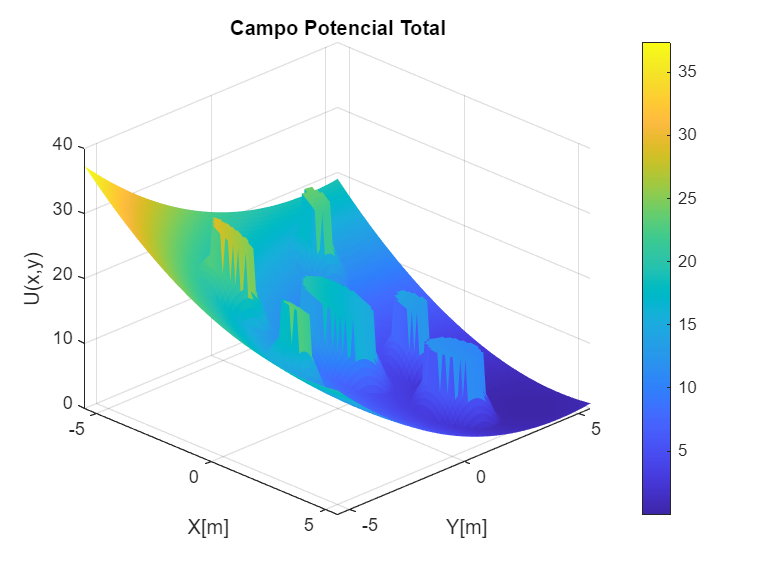


% 3. Crear campo potencial
alpha = 10; beta = 1; r_inf = k * 0.1; zeta = 0.2;
[xg, yg] = meshgrid(linspace(-1.2 * k, 1.2 * k, 100));
U_total = zeros(size(xg));
for i = 1:numel(xg)
    pos = [xg(i), yg(i)];
    d_att = pos - meta;
    U_att = zeta * norm(d_att)^2;
    U_rep = 0;
    for j = 1:length(RC)
        d_vec = pos - CC(j,:);
        d_norm = norm(d_vec);
        d_borde = d_norm - RC(j);
        if d_borde < r_inf && d_borde > 0
            U_rep = U_rep + alpha * tanh(beta * (r_inf - d_borde));
        elseif d_borde <= 0
            U_rep = U_rep + alpha;
        end
    end
    U_total(i) = U_att + U_rep;
end

% 4. Mostrar mapa 3D del campo potencial
figure
surf(xg, yg, U_total, 'EdgeColor', 'none')
title('Campo Potencial Total')
xlabel('X[m]'); ylabel('Y[m]'); zlabel('U(x,y)')
view(45, 30)
colorbar

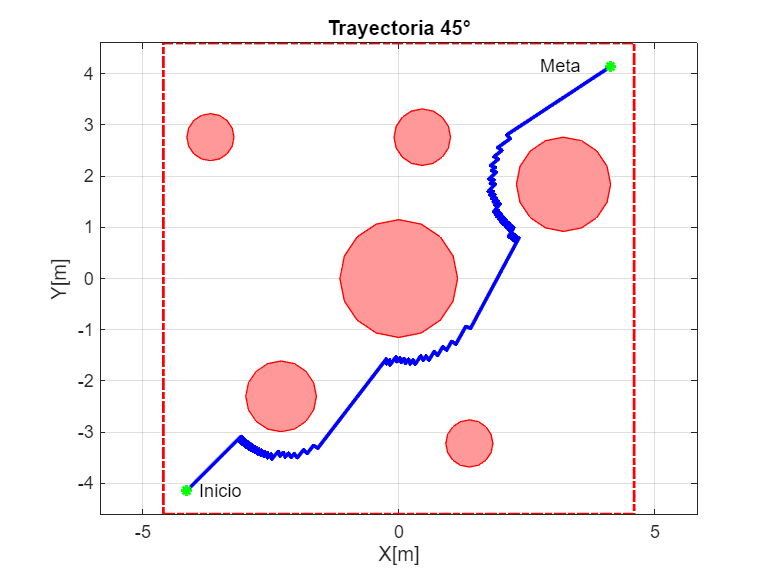


% 5. Calcular trayectoria (ángulo inicial como variable)
% ---------- CÁLCULO DE TRAYECTORIA CON CAMPO TANGENCIAL ----------
paso = 0.1;
tolerancia = 0.1;

orientacion_deg = 45;
dir_ini = [cosd(orientacion_deg), sind(orientacion_deg)];
pos = inicio;
tray = pos;

% Primer paso con dirección inicial
pos = pos + paso * dir_ini;
tray = [tray; pos];

for iter = 1:1000
    % Campo de atracción
    d_att = pos - meta;
    F_att = -2 * zeta * d_att;

    % Campos de repulsión y tangencial
    F_rep = [0 0];
    F_tan = [0 0];
    for j = 1:length(RC)
        d_vec = pos - CC(j,:);
        d_norm = norm(d_vec);
        d_borde = d_norm - RC(j);

        if d_borde < r_inf && d_borde > 0
            % Repulsión
            rep = alpha * beta * (1 - tanh(beta * (r_inf - d_borde))^2) * (d_vec / d_norm);
            F_rep = F_rep + rep;

            % Tangencial (calculada pero solo se usará si hay bloqueo)
            tangent = [-d_vec(2), d_vec(1)] / d_norm;
            peso = (r_inf - d_borde) / r_inf;
            F_tan = F_tan + 2 * peso * tangent;
        elseif d_borde <= 0
            % Repulsión máxima
            F_rep = F_rep + alpha * (d_vec / d_norm);
        end
    end

    % Magnitud de la fuerza sin tangencial
    F_base = F_att + F_rep;
    if norm(F_base) < 6  % Umbral de activación de tangencial
        F_total = F_base + F_tan;
    else
        F_total = F_base;
    end

    % Paso de integración normalizado
    pos = pos + paso * F_total / (norm(F_total) + 1e-6);
    tray = [tray; pos];

    % Condición de parada
    if norm(pos - meta) < tolerancia
        break
    end
end

% 6. Mostrar mapa con trayectoria
figure
plot(k*[-1 1 1 -1 -1],k*[-1 -1 1 1 -1],'r-.',LineWidth=1.5)
hold on
for i = 1:length(RC)
    fill(CC(i,1) + RC(i)*cos(t), CC(i,2) + RC(i)*sin(t), [1 0.6 0.6], 'EdgeColor', 'r')
end
plot(tray(:,1), tray(:,2), 'b-', 'LineWidth', 2)
plot(meta(1), meta(2), 'g*',LineWidth=1.5)
plot(inicio(1), inicio(2), 'g*',LineWidth=1.5)
text(-k*.85,-k*.9,'Inicio')
text(k*.6,k*.9,'Meta')
title(['Trayectoria ',num2str(orientacion_deg),'°'])
xlabel('X[m]')
ylabel('Y[m]')
axis equal
grid on

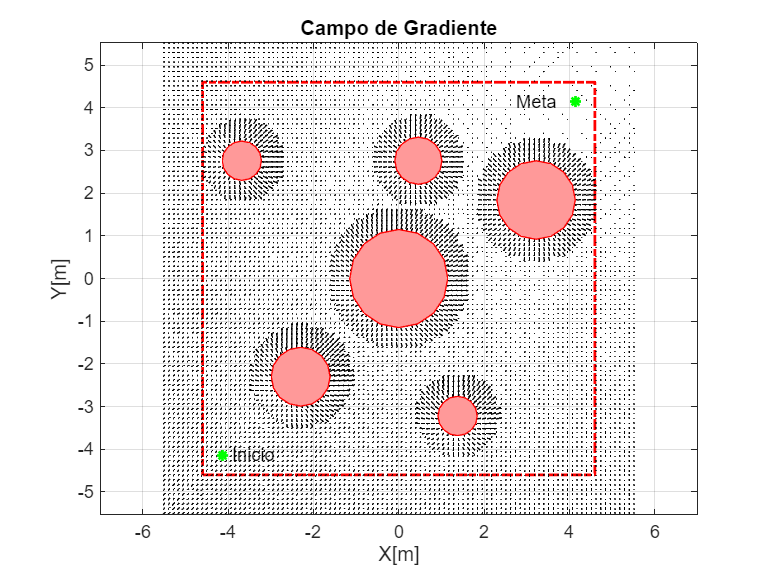


% 7. Mostrar campo de gradiente
Fx = zeros(size(xg));
Fy = zeros(size(yg));
for i = 1:numel(xg)
    pos = [xg(i), yg(i)];
    d_att = pos - meta;
    F_att = -2 * zeta * d_att;
    F_rep = [0 0];
    for j = 1:length(RC)
        d_vec = pos - CC(j,:);
        d_norm = norm(d_vec);
        d_borde = d_norm - RC(j);
        if d_borde < r_inf && d_borde > 0
            F_rep = F_rep + alpha * beta * (1 - tanh(beta * (r_inf - d_borde))^2) * (d_vec / d_norm);
        elseif d_borde <= 0
            F_rep = F_rep + alpha * (d_vec / d_norm);
        end
    end
    F_total = F_att + F_rep;
    Fx(i) = F_total(1);
    Fy(i) = F_total(2);
end

figure
plot(k*[-1 1 1 -1 -1],k*[-1 -1 1 1 -1],'r-.',LineWidth=1.5)
hold on
quiver(xg, yg, Fx, Fy, 'k')
for i = 1:length(RC)
    fill(CC(i,1) + RC(i)*cos(t), CC(i,2) + RC(i)*sin(t), [1 0.6 0.6], 'EdgeColor', 'r')
end
plot(meta(1), meta(2), 'g*',LineWidth=1.5)
plot(inicio(1), inicio(2), 'g*',LineWidth=1.5)
title('Campo de Gradiente')
text(-k*.85,-k*.9,'Inicio')
text(k*.6,k*.9,'Meta')
xlabel('X[m]')
ylabel('Y[m]')
axis equal
grid on